## **AERO95002 Numerical Analysis 2019-2020**

## **Coursework 1**

## **Dr. Elnaz Naghibi**

## **Due Date: 17 February 2020**

### **Question 1 [15%]**

Plot the function $f\left(x\right)=\cos \;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its roots using MATLAB functions.

Explore the four methods of root finding discussed in the lecture notes and select an efficient method to find each root. Discuss your rationale and provide the code presenting the most efficient method for each root. Show the convergence to each root using appropriate plots. Finally, compare the number of iterations required to obtain each root and discuss the reason behind the difference in convergence rates of the two roots.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

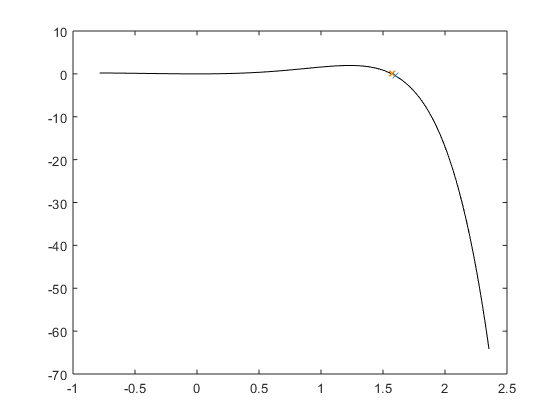

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.

%Question1;
clear
clc

x = -pi/4:0.01:pi*3/4;
%plot the diagram
%use newton method
plot(x,fx(x),'-k');
hold on;
x0 = 1.6;
tolerance = 0.00001;
while abs(fx(x0)) > tolerance
    plot(x0,fx(x0),'x');
    x1 = x0 - fx(x0)/fbarX(x0);
    x0 = x1;
    hold on
end

hold off;


fprintf('The root of this function is %4.3f.',x0);

The root of this function is 1.571.

### **Question 2 [30%]**

**Part a:  [15 %]**

Calculate Legendre polynomial of degree 5 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1\ldotp 1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of $\int_{-1}^2 \left({\textrm{ax}}^9 +{\textrm{bx}}^4 +\textrm{cx}\right)\;\textrm{dx}$ and show that it will be the same as its analytical value.

**Answer:**

%%Question 2a
clear
clc

N=5;
syms x;
Ln=1./(2.^N.*factorial(N)).*diff((x.^2-1).^N,N);
LnM = legendreP(5,x);
%x = -1:0.01:1;
x0=solve(Ln,x);
%get roots

ni=[];
for i =1:length(x0)
    if x0(i)>=-1 && x0(i)<=1
        ni = [ni,x0(i)];
    end
end
%ni calculated


wi = 2./(1-(ni).^2)*(diff(Ln,1)).^(-2);
valWi=[];
for i=1:5
    valWi(i) = subs(wi(i),x,ni(i));
end
%wi calculated;
disp(valWi);

    0.5689    0.4786    0.2369    0.4786    0.2369



%calculate the integration

dy = wi*fx2B(ni).';
disp(dy);

$$\begin{array}{l} \frac{2\,\left(\sigma_{8}-\sigma_{4}+\sigma_{6}\right)}{\sigma_{1}}-\frac{2\,\left(\sigma_{4}+\sigma_{8}+\sigma_{6}\right)}{\sigma_{1}}-\frac{2\,\left(\sigma_{7}-\sigma_{3}+\sigma_{5}\right)}{\sigma_{2}}+\frac{2\,\left(\sigma_{3}+\sigma_{7}+\sigma_{5}\right)}{\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\left(\sigma_{10}-\frac{4}{9}\right)\,\sigma_{9}\\ \sigma_{2}=\left(\sigma_{10}+\frac{4}{9}\right)\,\sigma_{9}\\ \sigma_{3}=2\,{\left(\sigma_{10}-\frac{5}{9}\right)}^{2}\\ \sigma_{4}=2\,{\left(\sigma_{10}+\frac{5}{9}\right)}^{2}\\ \sigma_{5}={\left(\frac{5}{9}-\sigma_{10}\right)}^{9/2}\\ \sigma_{6}={\left(\sigma_{10}+\frac{5}{9}\right)}^{9/2}\\ \sigma_{7}=2\,\sqrt{\frac{5}{9}-\sigma_{10}}\\ \sigma_{8}=2\,\sqrt{\sigma_{10}+\frac{5}{9}}\\ \sigma_{9}={\left(\frac{45\,x^{2}\,\left(x^{2}-1\right)}{2}+\frac{15\,{\left(x^{2}-1\right)}^{2}}{8}+15\,x^{4}\right)}^{2}\\ \sigma_{10}=\frac{2\,\sqrt{2}\,\sqrt{35}}{63} \end{array}$$

**Part b: [15 %]**

Use mid-point, trapezium and Simpson integration schemes to calculate the below integrals for $n=25,50,100,200$ and provide the code for each method accordingly.


$$\int_0^{3\pi } \textrm{sinx}\;\textrm{dx}$$



$$\int_0^{3\pi } \left|\mathrm{sinx}\right|\;\mathrm{dx}$$



$$\int_0^{3\pi } {\mathrm{sin}}^2 x\;\mathrm{dx}$$


Calculate the errors for every value of $n$ using analytical values of integration and list the order of accuracy of the schemes as you double $n$ in each round. Compare your calculated orders of accuracy with theoretical values in chapter 3.2 of the text book "‘Fundamentals of Engineering Numerical Analysis". Discuss how different choices of integrand functions can affect the order of accuracy in the numerical schemes. 

**Answer:**

%%question 2b
clear
clc

%midpoint methid
n=50;
h1 = 3*pi/n;
IntSinMid = 0;
for i = 0:n-1
    xmi = 0 + h1*((2*i + 1)/2);
    IntSinMid = IntSinMid + h1*sin(xmi);
end
fprintf('The intergral of sinx using mid-point rule is %3.3f',IntSinMid);

The intergral of sinx using mid-point rule is 2.003

%Trapezium rule
xi(1)=0;
for i = 1:n
    xi(i+1) = 0 + i*h1;
end
IntSinTrapz = 0;
for i = 1:n
    IntSinTrapz = IntSinTrapz + h1*((sin(xi(i)) + sin(xi(i+1)))/2);
end
fprintf('The integral of sinx using tapz is %3.3f',IntSinTrapz);

The integral of sinx using tapz is 1.994

%simpson rule
IntSinSim = 0;
%it can use ths same xi in trapz ruel
for i = 0:n
    if mod(i,2) == 0
        if (i==0) || (i==n)
            IntSinSim = IntSinSim + sin(xi(i+1));
        else
            IntSinSim = IntSinSim + 2*sin(xi(i+1));
        end
    
    else
        IntSinSim = IntSinSim + 4*sin(xi(i+1));
    end
end
IntSinSim = h1/3*IntSinSim;
fprintf('The integral of sinx using simpson is %3.3f',IntSinSim);

The integral of sinx using simpson is 2.000

%%Now is abs Sin(x)

IntAbsSinMid = 0;
for i = 0:n-1
    xmi = 0 + h1*((2*i + 1)/2);
    IntAbsSinMid = IntAbsSinMid + h1*abs(sin(xmi));
end
fprintf('The intergral of abs sinx using mid-point rule is %3.3f',IntAbsSinMid);

The intergral of abs sinx using mid-point rule is 6.001

%%using Trapz rule
%%using same xi

IntAbsSinTrapz = 0;
for i = 1:n
    IntAbsSinTrapz = IntAbsSinTrapz + h1*((abs(sin(xi(i))) + abs(sin(xi(i+1))))/2);
end
fprintf('The integral of abs sinx using tapz is %3.3f',IntAbsSinTrapz);

The integral of abs sinx using tapz is 5.998

%%Using Simpson rule
%%using same xi

IntAbsSinSim = 0;
for i = 0:n
    if mod(i,2) == 0
        if (i==0) || (i==n)
            IntAbsSinSim = IntAbsSinSim + abs(sin(xi(i+1)));
        else
            IntAbsSinSim = IntAbsSinSim + 2*abs(sin(xi(i+1)));
        end
    
    else
        IntAbsSinSim = IntAbsSinSim + 4*abs(sin(xi(i+1)));
    end
end
IntAbsSinSim = h1/3*IntAbsSinSim;
fprintf('The integral of abs sinx using simpson is %3.3f',IntAbsSinSim);

The integral of abs sinx using simpson is 6.000

%%Third equation
%midpoint methid

IntSin2Mid = 0;
for i = 0:n-1
    xmi = 0 + h1*((2*i + 1)/2);
    IntSin2Mid = IntSin2Mid + h1*sin(xmi)^2;
end
fprintf('The intergral of sinx^2 using mid-point rule is %3.3f',IntSin2Mid);

The intergral of sinx^2 using mid-point rule is 4.712

%Trapz rule

### **Question 3 [25%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\cosh \;x}$ in the interval $\left\lbrack -2,2\right\rbrack$. Write a code to calculate the cubic spline passing though these points. Increase the number of points to 15 and rebuild the cubic spline. Compare your results with equally-spaced arrays of function values for n=5 and n=15 and report the Euclidean norm of error in each case.

**Answer:**

### **Question 4 [30%]**

**Part a: [15 %]**

Using the MATLAB command "meshgrid", create a $100\;\times \;100$ grid on the interval $x,y$$\in \left\lbrack -1,1\right\rbrack$. Create the discretized values of the function $f\left(x,y\right)=x^3 +3{\textrm{yx}}^2$ in this interval. Calculate 2D distributions of $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ using finite difference schemes (use central difference for interior points and forward/backward difference for the points on the boundary). Plot the numerically calculated profiles of  $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ on planes$x=0$ and $y=0\ldotp 5$and compare them with the analytical profiles of the derivatives.

**Answer:**

**Part b: [15 %]**

Use the systematic method to construct the finite-difference approximation of  $\frac{{\mathrm{d}}^4 f}{\mathrm{d}x^4 }$ using the stencil $\left(-2,-1,0,1,2\right)$. Report the coefficients obtained and the order of the truncation error in this approximation. Comment under which circumstance this approximation will provide an exact solution.

**Answer:**

function y = fx(x)
 y = cos(x).*(exp(2.*x) - 2.*exp(x) + 1);
end

function dydx = fbarX(x)
 dydx = -sin(x) .*(exp(2.*x) - 2.*exp(x) + 1) + cos(x) .*(2.*exp(2.*x) - 2.*exp(x));  
end

function y = fx2B(x)
 y=x.^9+2.*x.^4+2.*x;
end